## Change of coordinates

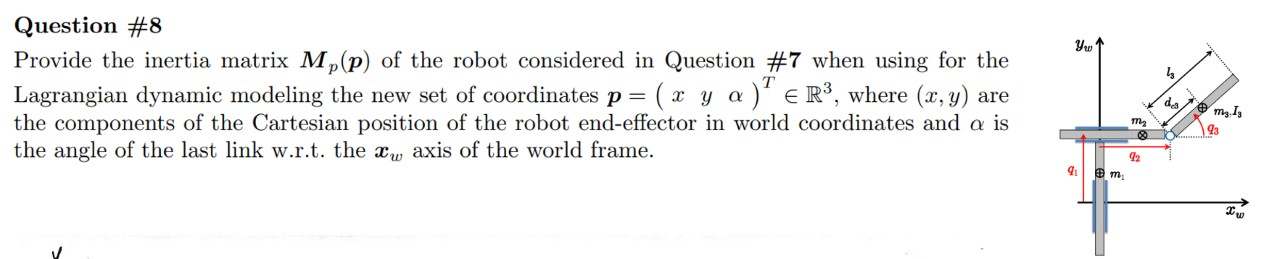

syms q1 q2 q3 p1 p2 p3 l1 l2 l3 positive
syms m1 m2 m3 I3 d3

% Computed by hand
p = [q2+l3*cos(q3);
     q1+l3*sin(q3);
          q3;];
q = [p2-l3*sin(q3);
     p1-l3*cos(q3);
         p3;];
% Jacobian
J = jacobian(p,[q1,q2,q3]);
J_inv = inv(J);

% Inertia Matrix with change of coordinates
M_q = [m1+m2+m3            0           d3;
          0              m2+m3      -d3*m3*sin(q3);
      d3*m3*cos(q3)  -d3*m3*sin(q3)    m3*(d3^2)*I3;];
M_p = J_inv.'*M_q*J_inv

$$M\_p = \begin{array}{l} \left(\begin{array}{ccc} m_{2}+m_{3} & 0 & \sigma_{2}\\ 0 & m_{1}+m_{2}+m_{3} & d_{3}-l_{3}\,\cos\left(q_{3}\right)\,\left(m_{1}+m_{2}+m_{3}\right)\\ \sigma_{2} & \sigma_{1} & I_{3}\,{d_{3}}^{2}\,m_{3}-l_{3}\,\sin\left(q_{3}\right)\,\left(d_{3}\,m_{3}\,\sin\left(q_{3}\right)-l_{3}\,\sin\left(q_{3}\right)\,\left(m_{2}+m_{3}\right)\right)-l_{3}\,\cos\left(q_{3}\right)\,\sigma_{1}-d_{3}\,l_{3}\,\cos\left(q_{3}\right)-d_{3}\,l_{3}\,m_{3}\,{\sin\left(q_{3}\right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{3}\,m_{3}\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{3}\right)\,\left(m_{1}+m_{2}+m_{3}\right)\\ \sigma_{2}=l_{3}\,\sin\left(q_{3}\right)\,\left(m_{2}+m_{3}\right)-d_{3}\,m_{3}\,\sin\left(q_{3}\right) \end{array}$$